clc
clear all

## Regresión Lineal

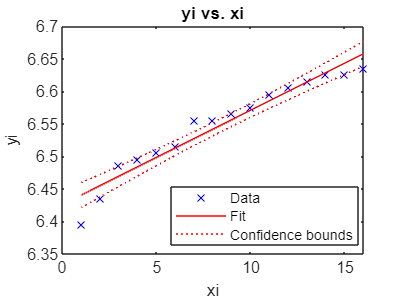

table1 = readtable("datos_regresion.csv");
reg = fitlm(table1);

figure(1)
plot(reg)

## Regresión No Lineal

table2 = readtable("datos_regresion_multiple.csv");
x = table2.x1;
y = table2.y;
vec = polyfit(x,y,2);
x_reg = min(x):1:max(x);

figure(2)
hold on
a1 = plot(x_reg,polyval(vec,x_reg),"LineWidth",2);

a1 =   Line with properties:

              Color: [0.4660 0.6740 0.1880]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7]
              YData: [5.1961 4.1901 4.5037 6.1368 9.0896 13.3618 18.9537 25.8651]

  Show all properties


a2 = plot(x,y,"LineWidth",2);

a2 =   Line with properties:

              Color: [0.3010 0.7450 0.9330]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 2 2.5000 1 4 7]
              YData: [5 10 9 0 3 27]

  Show all properties


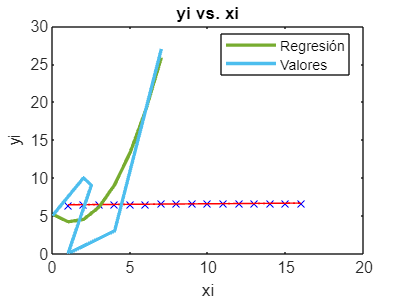

legend([a1,a2],"Regresión","Valores")
hold off

## Regresión Multiple

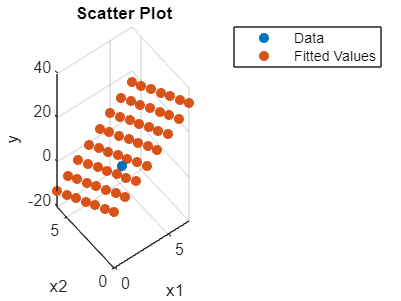

%
% Assuming you have the variables `table2.x1`, `table2.x2`, and `table2.y` available

% Create a matrix of predictors X and the response variable y
X = [ones(size(table2.x1)), table2.x1, table2.x2, table2.x1 .* table2.x2];
y = table2.y;

% Perform multiple linear regression
b = regress(y, X);

% Generate a meshgrid for the fitted values
x1fit = min(table2.x1):1:max(table2.x1);
x2fit = min(table2.x2):1:max(table2.x2);
[X1, X2] = meshgrid(x1fit, x2fit);

% Calculate the fitted values using the regression coefficients
yfit = b(1) + b(2) * X1 + b(3) * X2 + b(4) * X1 .* X2;

% Create a 3D scatter plot of the data
figure(3);
scatter3(table2.x1, table2.x2, y, 'filled');
xlabel('x1');
ylabel('x2');
zlabel('y');
title('Scatter Plot');
% Plot the fitted values on the 3D scatter plot
hold on;
scatter3(X1(:), X2(:), yfit(:), 'filled');
legend('Data', 'Fitted Values');
hold off;